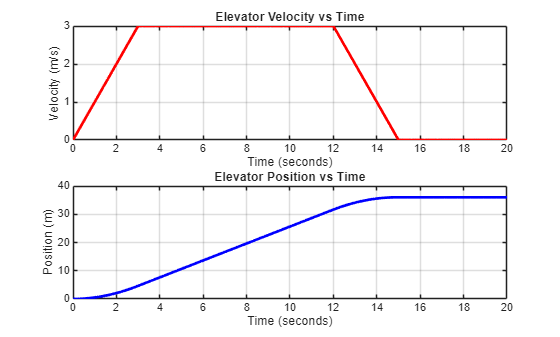

% Author: Christopher Bourjaili
% Module 2
% Project 9
% Title: Elevator Motion Profile
%
% Summary of Code:
% - Simulates elevator movement between floors over time.
% - Uses acceleration, cruise, and deceleration phases.
% - Applies piecewise motion logic for each travel stage.
% - Updates velocity and position at each time step.
% - Creates velocity vs time and position vs time plots.
% - Evaluates ride smoothness through gradual speed changes.
%
% What I Learned:
% This project demonstrated how MATLAB can model controlled mechanical
% motion using kinematics, loops, and segmented logic. I learned that
% smooth elevator rides depend on gradual acceleration and deceleration
% rather than sudden speed changes. I also practiced simulating piecewise
% motion profiles commonly used in transportation systems.

clc
clear
close all

dt = 0.1;                 
t_total = 20;             

t = 0:dt:t_total;
n = length(t);

a = 1.0;                  
v_max = 3.0;              

position = zeros(1,n);
velocity = zeros(1,n);

for i = 2:n

    if t(i) <= 4
        accel = a;
        
    elseif t(i) <= 12
        accel = 0;
        
    elseif t(i) <= 16
        accel = -a;
        
    else
        accel = 0;
        velocity(i-1) = max(velocity(i-1),0);
    end

    velocity(i) = velocity(i-1) + accel*dt;

    if velocity(i) < 0
        velocity(i) = 0;
    end

    if velocity(i) > v_max
        velocity(i) = v_max;
    end

    position(i) = position(i-1) + velocity(i)*dt;
    
end

figure

subplot(2,1,1)
plot(t, velocity,'r','LineWidth',2)
grid on
xlabel('Time (seconds)')
ylabel('Velocity (m/s)')
title('Elevator Velocity vs Time')

subplot(2,1,2)
plot(t, position,'b','LineWidth',2)
grid on
xlabel('Time (seconds)')
ylabel('Position (m)')
title('Elevator Position vs Time')


disp('Ride Smoothness Analysis:')

Ride Smoothness Analysis:


disp('1. Gradual acceleration improves passenger comfort.')

1. Gradual acceleration improves passenger comfort.


disp('2. Constant cruise speed provides stable motion.')

2. Constant cruise speed provides stable motion.


disp('3. Smooth deceleration reduces sudden stopping forces.')

3. Smooth deceleration reduces sudden stopping forces.


disp('4. Piecewise motion creates efficient and comfortable travel.')

4. Piecewise motion creates efficient and comfortable travel.
